# Sum of two random variables

Given two independent random variables $X$ and $Y$ where both are equally distributed with the following probability density functions


$$f_X(x) = \frac{\mathrm{rect}\left((x-2)/4\right)}{4} \qquad\mbox{and}\qquad f_Y(y) = \frac{\mathrm{rect}\left(y/2\right)}{2}$$


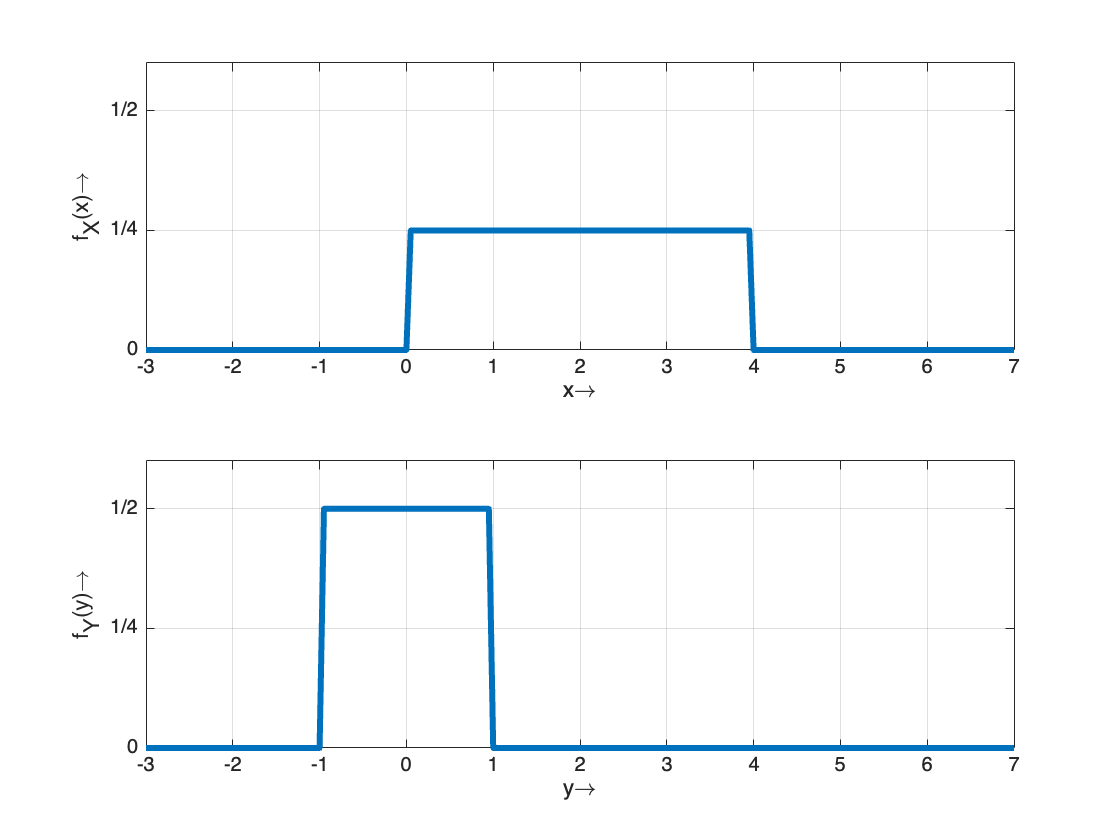

rect = @(x) double(abs(x)<1/2);

fX = @(x) rect((x-2)/4)/4;
fY = @(y) rect(y/2)/2;

dx = 0.05;
x = -3:dx:7;
y = x;

figure
ax1 = subplot(211);
plot(x, fX(x), linewidth=3)
xlabel('x\rightarrow')
ylabel('f_X(x)\rightarrow')
xlim(x([1, end]))
ylim([-inf, .6])
set(gca, 'XTick', x(1):x(end))
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on
ax2 = subplot(212);
plot(y, fY(y), linewidth=3)
xlabel('y\rightarrow')
ylabel('f_Y(y)\rightarrow')
set(gca, 'XTick', x(1):x(end))
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on
linkaxes([ax1, ax2])

We are now looking for the probability density function of the sum of these two random variables


$$Z = X+Y$$


## Analytic calculation of the probability density function of Z

Since $X$ and $Y$ are statistically independent, we can calculate the probability density function of $Z$ through the convolution


$$f_Z(z) = f_X(z) \ast f_Y(z) = \int\limits_{-\infty}^{+\infty} f_X(x) \cdot f_Y(z-x)\,\mathrm{d}x$$


We can simply calculate this convolution as

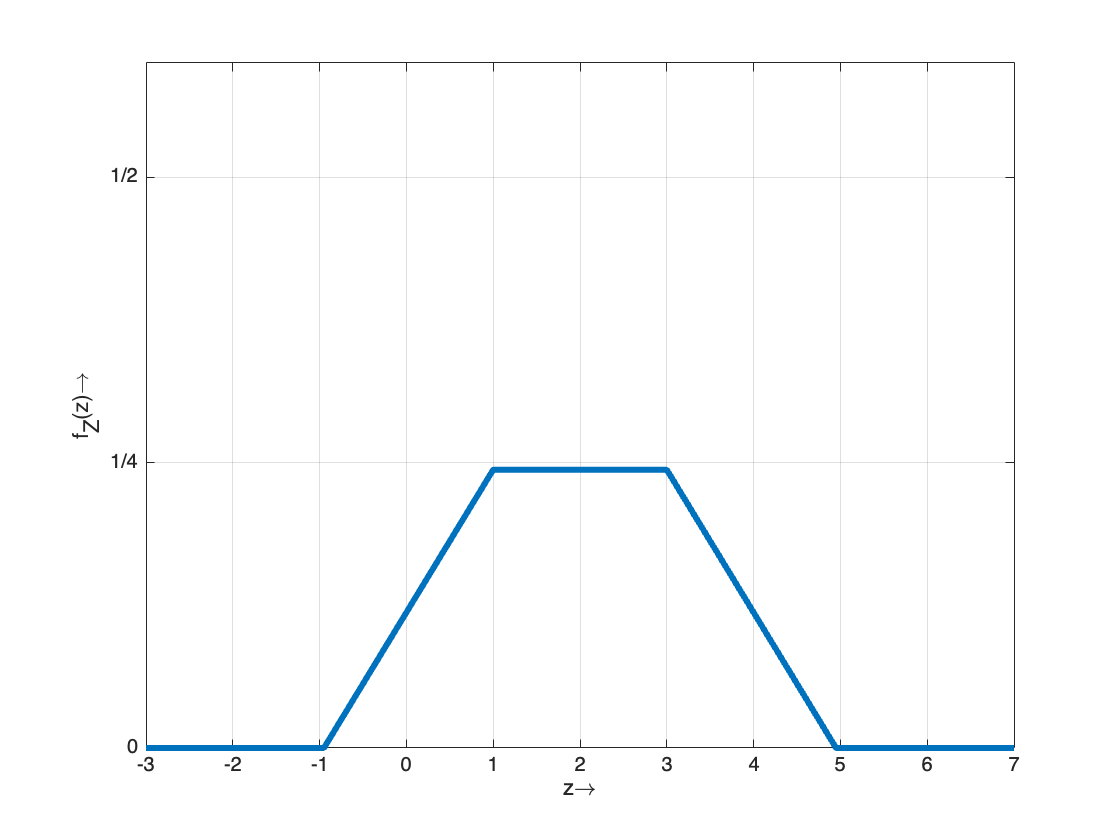

fZ = conv(fX(x), fY(y))*dx;
z = x(1)+y(1):dx:x(end)+y(end);

figure
plot(z, fZ, linewidth=3)
xlabel('z\rightarrow')
ylabel('f_Z(z)\rightarrow')
xlim(x([1, end]))
ylim([-inf, .6])
set(gca, 'XTick', -3:7)
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on

## Approximation of the probability density function of Z by simulating random variables

First, we create samples of the random variables $X$ and $Y$ and plot the respective histograms.

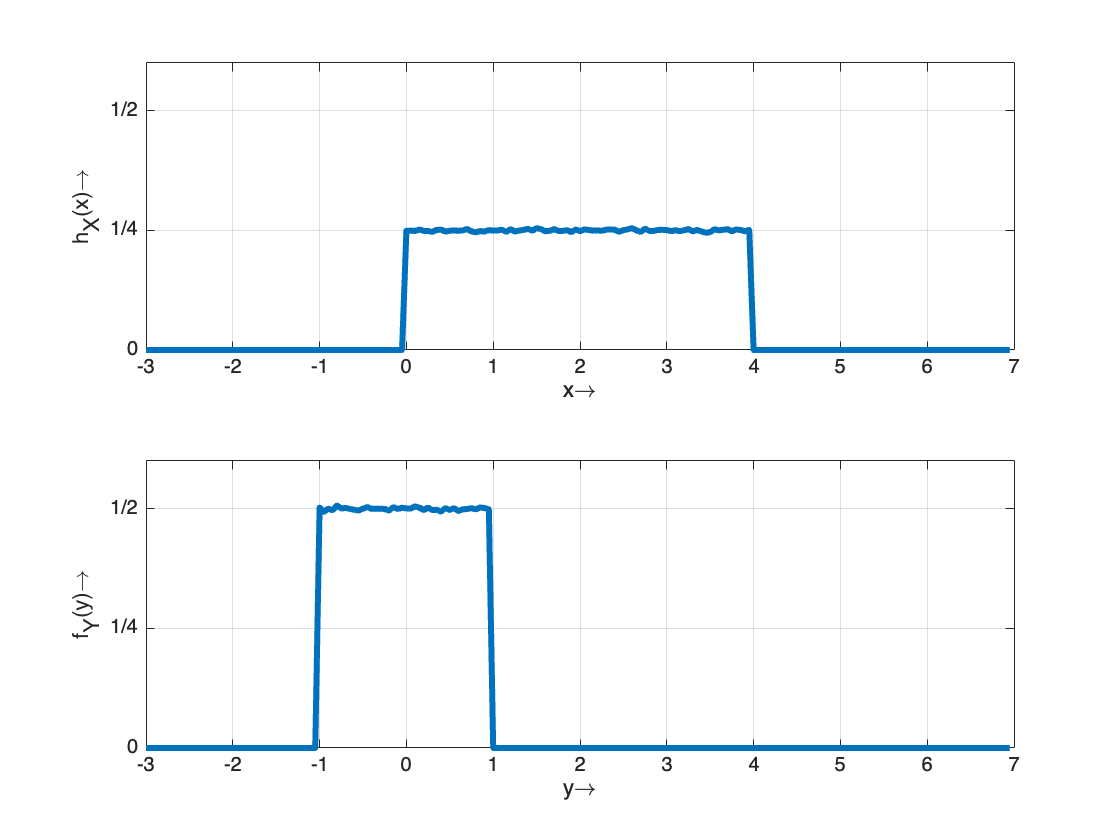

N = 1000000;
X = 4*rand(1,N);
Y = 2*rand(1,N)-1;

hX = histcounts(X, x, normalization='pdf');
hY = histcounts(Y, y, normalization='pdf');

figure
ax1 = subplot(211);
plot(x(1:end-1), hX, linewidth=3)
xlabel('x\rightarrow')
ylabel('h_X(x)\rightarrow')
xlim(x([1, end]))
ylim([-inf, .6])
set(gca, 'XTick', x(1):x(end))
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on
ax2 = subplot(212);
plot(y(1:end-1), hY, linewidth=3)
xlabel('y\rightarrow')
ylabel('f_Y(y)\rightarrow')
set(gca, 'XTick', x(1):x(end))
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on
linkaxes([ax1, ax2])

Now, we create the random variable $Z$ and plot its historam

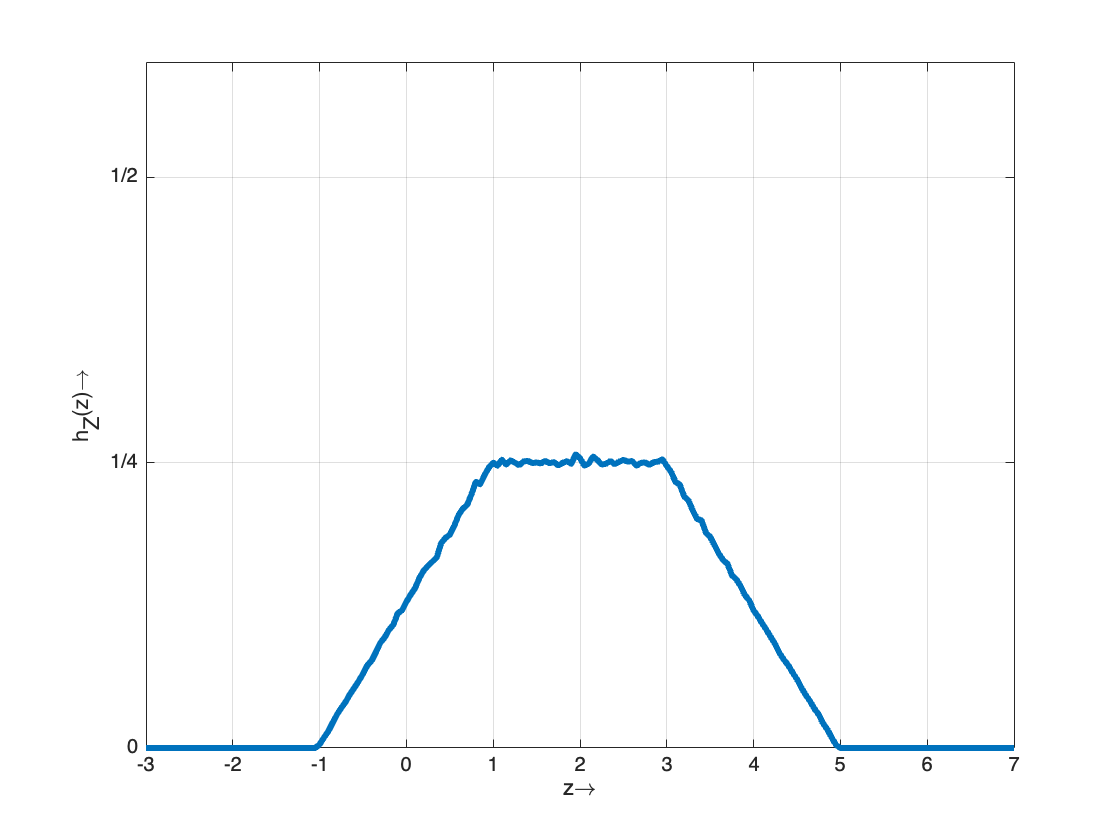

Z = X+Y;

hZ = histcounts(Z, z, normalization='pdf');

figure
plot(z(1:end-1), hZ, linewidth=3)
xlabel('z\rightarrow')
ylabel('h_Z(z)\rightarrow')
xlim(x([1, end]))
ylim([-inf, .6])
set(gca, 'XTick', x(1):x(end))
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on

## Comparision of analytic and simulation result

Finally, we can compare both results in order to show that the analytic calculation through the convolution of $f_X(x)$ and $f_Y(y)$ match the simulation results.

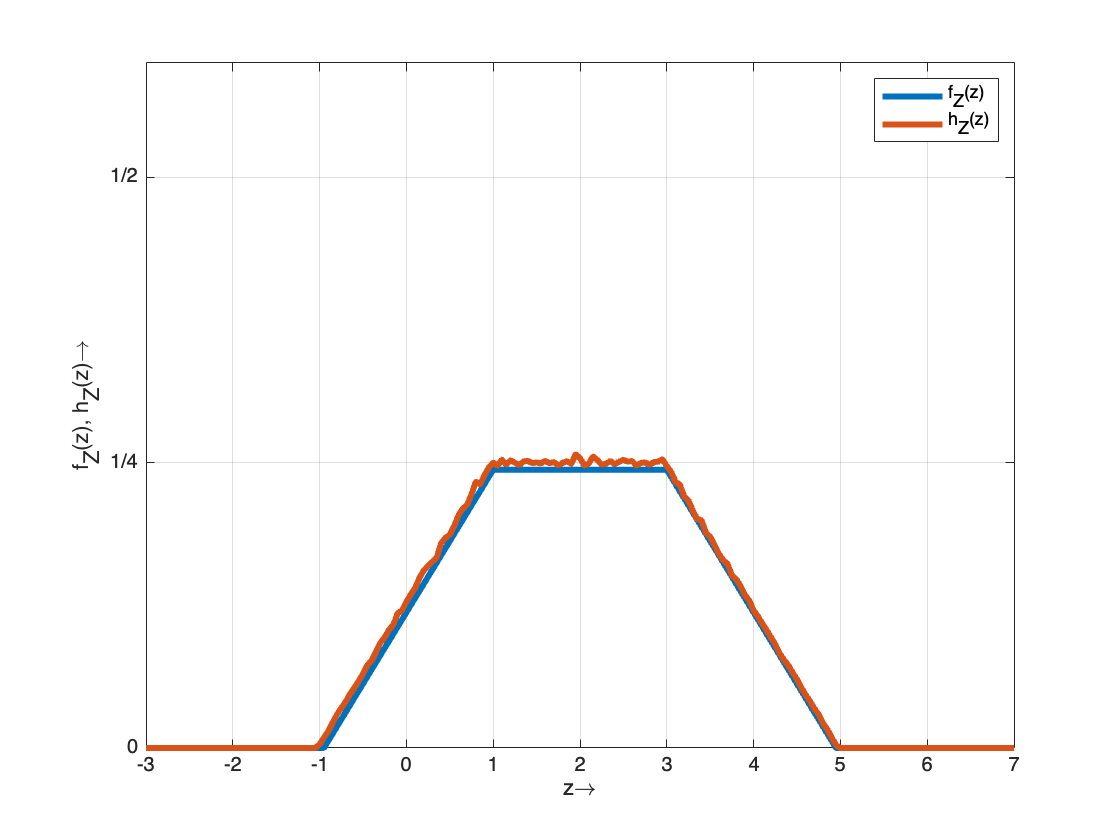

figure
plot(z, fZ, linewidth=3)
hold on
plot(z(1:end-1), hZ, linewidth=3)
xlabel('z\rightarrow')
ylabel('f_Z(z), h_Z(z)\rightarrow')
xlim(x([1, end]))
ylim([-inf, .6])
set(gca, 'XTick', x(1):x(end))
set(gca, 'YTick', [0, 1/4, 1/2])
set(gca, 'YTicklabel', {'0', '1/4', '1/2'})
grid on
legend('f_Z(z)', 'h_Z(z)')